## Sistema Ball & Beam

clear all;
close all;

format long g

### Constantes

Tempo de amostragem

Ts = 19e-3; %s

### Modelo do sistema

% modelo mola forte
coefA = [
        -0.565226745901493
        -0.147586643392935
         0.304242172000966
       0.00538050249672198
        -0.067355248576711
];

coefB = [
         0.299578174721714
        -0.383620653895442
       -0.0402082391731603
         0.034053455293313
         0.090257543531445
];

% modelo mola media
% coefA = [
%         -0.529595214929287
%         -0.485010316061038
%          0.225636271019077
%        -0.0485043700385894
%        -0.0613224476230946
% ];
% 
% coefB = [
%         0.0371790900110465
%         -0.073400009236704
%         0.0377270917609542
%      -2.76847604474093e-05
%        -0.0015003834159776
% ];

% A = ss1.A;
% B = ss1.B;
% C = ss1.C;
% D = ss1.D;
% 
% C = [C ; zeros(1, size(C, 2))];
% D = [D ; 0];


A = [-1*coefA(1:end-1) eye(size(coefA, 1)-1); 
     -1*coefA(end, 1) zeros(1, size(coefA, 1)-1)]

A =          0.565226745901493                         1                         0                         0                         0
         0.147586643392935                         0                         1                         0                         0
        -0.304242172000966                         0                         0                         1                         0
      -0.00538050249672198                         0                         0                         0                         1
         0.067355248576711                         0                         0                         0                         0


B = [coefB]

B =          0.299578174721714
        -0.383620653895442
       -0.0402082391731603
         0.034053455293313
         0.090257543531445


C = [1 zeros(1, size(A, 1)-1)]

C =      1     0     0     0     0


D = [0];
sysD = ss(A, B, C, D, 'Ts', Ts)

sysD =
 
  A = 
              x1         x2         x3         x4         x5
   x1     0.5652          1          0          0          0
   x2     0.1476          0          1          0          0
   x3    -0.3042          0          0          1          0
   x4  -0.005381          0          0          0          1
   x5    0.06736          0          0          0          0
 
  B = 
             u1
   x1    0.2996
   x2   -0.3836
   x3  -0.04021
   x4   0.03405
   x5   0.09026
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.019 seconds
Discrete-time state-space model.



### Projeto do controlador Hinf

Acell{1} = sysD.A;
Bcell{1} = sysD.B;
Bw{1} = [1 zeros(1, size(sysD.A, 1)-1)]';
% Du = [zeros(1, size(C, 1)-1) 1]';
% Dw = [zeros(1, size(C, 1))]';

Du = [0]';
Dw = [0]';

saturacao = 40; % pwm

[K,hinf,P] = hinf_discrete_sat_V2(Acell, Bcell, sysD.C, Du, Dw, Bw, saturacao);

MOSEK Version 10.1.22 (Build date: 2024-1-21 21:42:40)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 27              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2 (scalarized: 112)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pri

[K2,h2,P2] = h2_discrete(Acell, Bcell, sysD.C, Du, Dw, Bw, saturacao);

MOSEK Version 10.1.22 (Build date: 2024-1-21 21:42:40)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 21              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 3 (scalarized: 142)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pri

Ganhos do controlador

disp(K');

         0.731624315338357
          2.70021968222051
          5.40674670420982
          6.09668923410015
          6.50916075207539



disp(K2');

         -1.34216705215132
          -2.2099873300152
          1.06310444625557
         0.995545083167062
          0.92790872284339



Autovalores da matriz P

disp(eig(P))

         0.175271786770766
         0.728266391550126
          1.37695499119166
          2.77652897094957
          38.1273668247413



disp(eig(P2))

       8.9761095226508e-05
      0.000415542009678476
        0.0160447733403487
         0.953660500026185
           2.3355611269659



Norma $H_{\infty }$

disp(hinf)

          1.88869665824468



disp(h2)

          1.06513816809902



### Amostragens

N = 1000;

### Simulação

A = sysD.A;
B = sysD.B;
C = sysD.C;
D = sysD.D;

#### Condições iniciais

x_real{1} = [-5 zeros(1, size(A, 1)-1)]';
% x_ruido{1} = x_real{1} + U * w(:,1);

Estimadas

x_priori{1} = zeros(size(A, 1), 1);
x_hat{1} = zeros(size(A, 1), 1);
% y_hat(1) = C * x_hat{1};
% P_hat{1} = diag([0 0]);

Simulação do sistema discreto

for k = 1:N
    
    u(k) = K * x_real{k};

    % Saturar entrada

    if u(k) >= saturacao
        u(k) = saturacao;
    end

    if u(k) <= -saturacao
        u(k) = -saturacao;
    end

    % Sistema real  
    if u(k) >= 700
        x_real{k+1} = A * x_real{k} + B * u(k) + Bw{1} * 5 * sin(2*pi*k*1/1000);
        y_real(:, k+1) = C * x_real{k+1};   
    else
        x_real{k+1} = A * x_real{k} + B * 0 + Bw{1} * 5 * sin(2*pi*k*1/1000);
        y_real(:, k+1) = C * x_real{k+1};   
    end
        
%     y_dot(k+1) = [0 1] * x_real{k+1};

%     % Sistema com ruído
%     x_ruido{k+1} = A * x_real{k} + B * u(k) + U * w(:,k);
%     y_ruido(k+1) = C * x_real{k+1} + v(:, k);
%     y_dot_ruido(k+1) = [0 1] * x_real{k+1} + v(:,k);

end

### Gráficos

#### Esfera

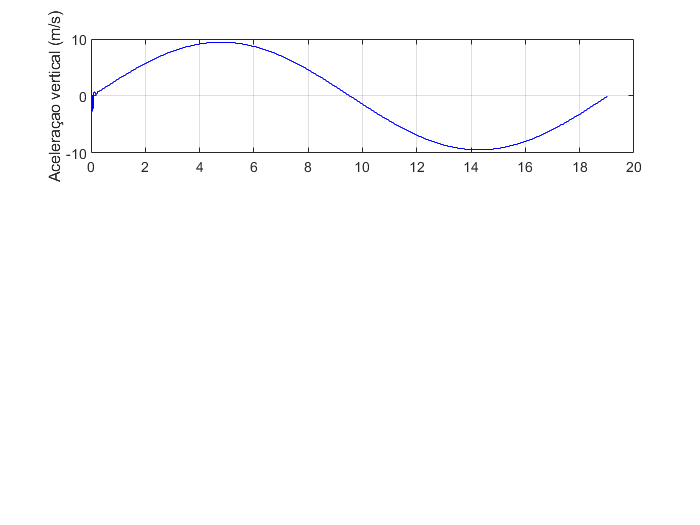

k = 1:N+1;

figure
hold on
subplot(3,1,1)
stairs(k*Ts, y_real(1, :), 'b');
ylabel("Aceleraçao vertical (m/s)")
grid
hold off

% subplot(3,1,2)
% hold on
% stairs(k*Ts, y_real(2, :), 'b');
% ylabel("SL Position (deg)")
% grid
% hold off
% 
% subplot(3,1,3)
% hold on
% stairs(k*Ts, y_real(3, :), 'b');
% ylabel("Arm position (deg)")
% grid
% hold off

% legend("Posição real", "Posição estimada", "Posição com ruído");
grid on
hold off

#### Sinal de controle

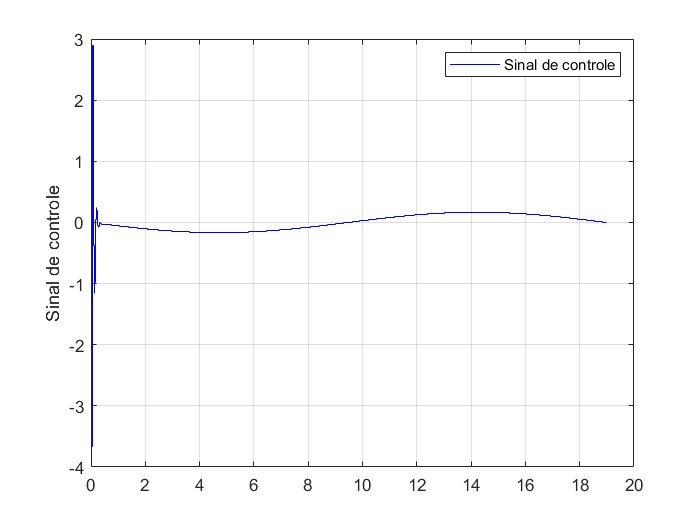

k = 1:N;

figure
stairs(k*Ts, u, 'b');
ylabel("Sinal de controle")
legend("Sinal de controle");
grid on